clear 
a = 5;
b = 8;
c = 15;
l = 20;
k1 = 5.6;
k2 = 5.6;
k3 = 5.6;
k4 = 5.6;
syms x
% x = [x,y1,y2]
f = @(x)k1*x(2)+k2*sqrt((x(1))^2+(a-x(2))^2)+k3*sqrt((c-x(1))^2+(x(3)-x(2))^2)+k4*sqrt((l-c)^2+(b-x(3))^2);
x0 = [1,1,1];
lb = [0,0,a];
ub = [c,a,b];
[x1,val] = fmincon(f,x0,[],[],[],[],lb,ub);


找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


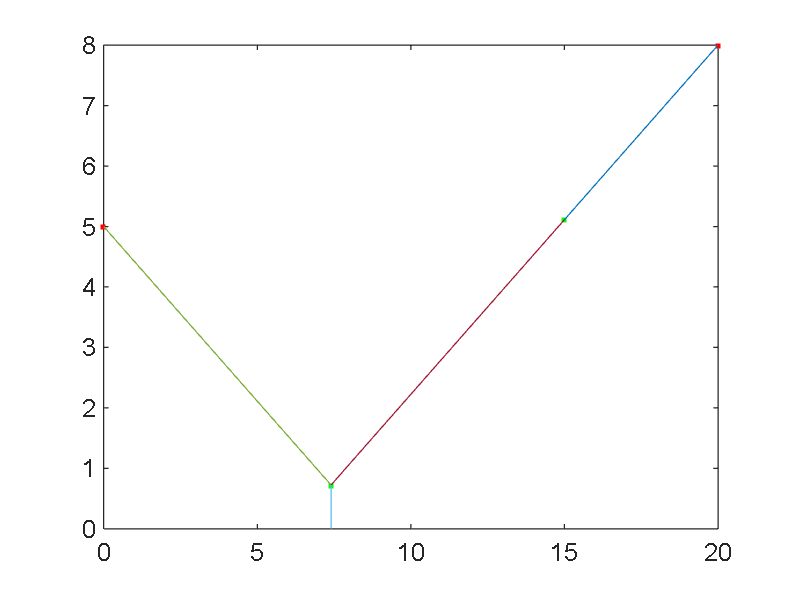

plot(0,a,'.r',x1(1),x1(2),'.g',c,x1(3),'.g',l,b,'.r');
% line 连线函数，横坐标纵坐标分别放进一个数组
line([0,x1(1)],[a,x1(2)]);
line([x1(1),x1(1)],[0,x1(2)]);
line([x1(1),c],[x1(2),x1(3)]);
line([c,l],[x1(3),b]);